clear all
d1=load("precipitation\PPT_zscore.mat");
d2=load("Soil moisture\SM_zscore.mat");
d3=load("L band VOD\VOD_zscore.mat");
d4=load("SIF data\SIF_zscore.mat");
d5=load("SPI weekly\SPI_1month_08_18.mat");
d6=load("VODCA VOD\VOD_X_zscore.mat");
d7=load("VODCA VOD\VOD_C_zscore.mat");
d8=load("ndvi.mat");


ppt=d1.Z(:,:,1:132);
sm=d2.Z(:,:,1:132);
vod=d3.Z(:,:,1:132);
sif=d4.Z(:,:,1:132);
spi=d5.SPI(:,:,1:132);
vod_x=d6.Z(:,:,1:132);
vod_c=d7.Z(:,:,1:132);
ndvi=d8.NDVI;

year=2014;
sc=3;
x1=99;
y1=47;
lat=ppt(x1,1,1);
long=ppt(1,y1,1);

for p=1:132
    if (floor(ppt(1,1,p)/100))==year
        ind_start=p;
        break
    end
end
ind_end=ind_start+11;

mo=1:12;

for k=1:12
    m(k)=month(datetime(1,k,1), 'name');
end

mon=["Jan","Feb","Mar","Apr","May","Jun","Jul","Aug","Sep","Oct","Nov","Dec"]';

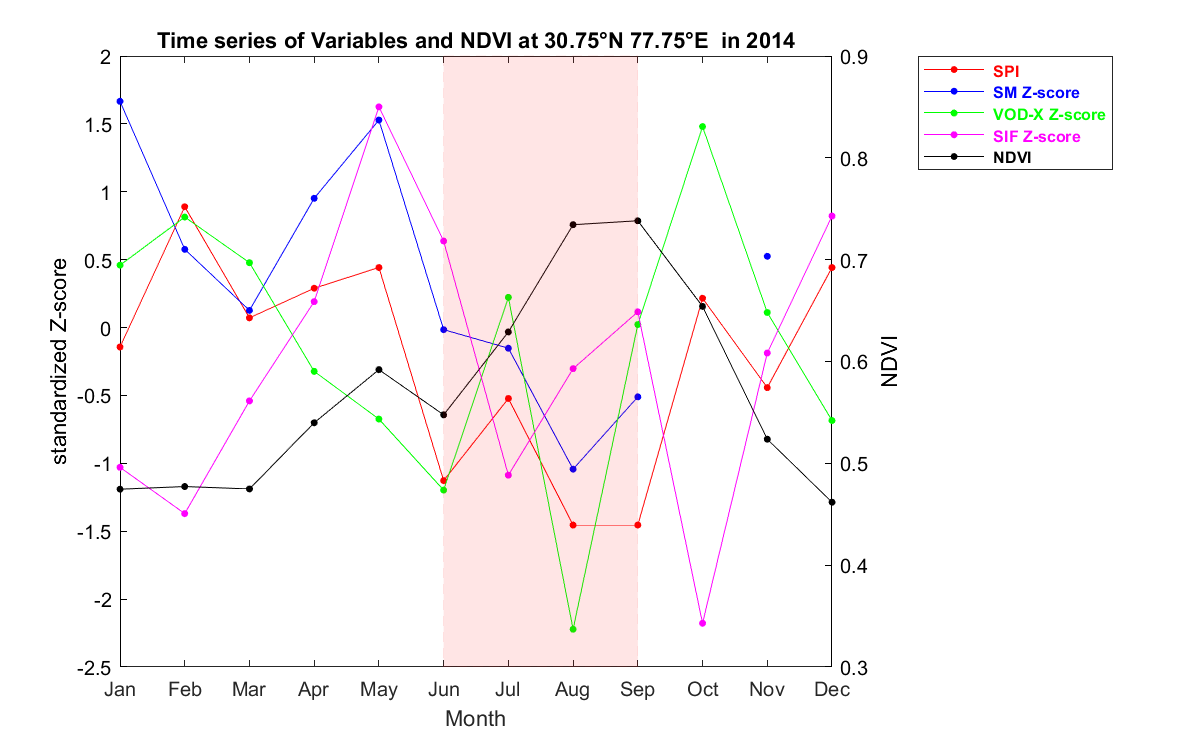

for x=x1      %lat values 2:130
    for y=y1     %long values 2:136
        
        p=squeeze(spi(x,y,ind_start:ind_end));
        s=squeeze(sm(x,y,ind_start:ind_end));
        si=squeeze(sif(x,y,ind_start:ind_end));
        v=squeeze(vod_x(x,y,ind_start:ind_end));
        nd=squeeze(ndvi(x,y,ind_start:ind_end));
        
        
        f1=figure(1);
        plot(p,"-o",'MarkerSize',3,'MarkerEdgeColor','red','MarkerFaceColor',"red","Color","red");
        xlim([1 12]);
        %xticklabels(["jan","feb","mar","apr","may","jun","jul","aug","sep","oct","nov","dec"]);
        set(gca,'xticklabel',mon);
        hold on
        plot(s,"-o",'MarkerSize',3,'MarkerEdgeColor','b','MarkerFaceColor',"b","Color","b");
        plot(v,"-o",'MarkerSize',3,'MarkerEdgeColor','g','MarkerFaceColor',"g","Color","g");
        plot(si,"-o",'MarkerSize',3,'MarkerEdgeColor','m','MarkerFaceColor',"m","Color","m");
        %         j=yline(0);
        %         j.Annotation.LegendInformation.IconDisplayStyle = 'off';
        ylabel("standardized Z-score")
        yyaxis right
        plot(nd,"-o",'MarkerSize',3,'MarkerEdgeColor','k','MarkerFaceColor',"k","Color","k");
        xlim([1 12]);
        ylim([0.3 0.9])
        ylabel("NDVI")
        lgd=legend("\color{red}\bf SPI","\color{blue}\bf SM Z-score","\color{green}\bf VOD-X Z-score","\color{magenta}\bf SIF Z-score","\color{black}\bf NDVI");
        lgd.FontSize=8;
%         legend boxoff;
        legend('Location','northeastoutside')
        xlabel("Month");
        title("Time series of Variables and NDVI"+" at "+num2str(lat)+"°N "+num2str(long)+"°E "+" in "+num2str(year))%+" ("+num2str(sc)+" month lag)");
        %         j=jbfill((1:12),p_st_u',p_st_d',"g","g",1,0.25);
        %         j.Annotation.LegendInformation.IconDisplayStyle = 'off';
        ax = gca;
        ax.YAxis(1).Color = 'k';
        ax.YAxis(2).Color = 'k';
        lim=get(gca,'ylim');
        up=[lim(2),lim(2),lim(2),lim(2)];
        do=[lim(1),lim(1),lim(1),lim(1)];
        q=jbfill((6:9),up,do,"r","r",1,0.1);
        q.Annotation.LegendInformation.IconDisplayStyle = 'off';
        %         q=jbfill((9:12),up,do,"r","r",1,0.1);
        %         q.Annotation.LegendInformation.IconDisplayStyle = 'off';
        x0=10;
        y0=10;
        width=800;
        height=500;
        set(gcf,'position',[x0,y0,width,height])
        hold off
        
    end
end

function[fillhandle,msg]=jbfill(xpoints,upper,lower,color,edge,add,transparency)
%USAGE: [fillhandle,msg]=jbfill(xpoints,upper,lower,color,edge,add,transparency)
%This function will fill a region with a color between the two vectors provided
%using the Matlab fill command.
%
%fillhandle is the returned handle to the filled region in the plot.
%xpoints= The horizontal data points (ie frequencies). Note length(Upper)
%         must equal Length(lower)and must equal length(xpoints)!
%upper = the upper curve values (data can be less than lower)
%lower = the lower curve values (data can be more than upper)
%color = the color of the filled area
%edge  = the color around the edge of the filled area
%add   = a flag to add to the current plot or make a new one.
%transparency is a value ranging from 1 for opaque to 0 for invisible for
%the filled color only.
%
%John A. Bockstege November 2006;
%Example:
%     a=rand(1,20);%Vector of random data
%     b=a+2*rand(1,20);%2nd vector of data points;
%     x=1:20;%horizontal vector
%     [ph,msg]=jbfill(x,a,b,rand(1,3),rand(1,3),0,rand(1,1))
%     grid on
%     legend('Datr')
if nargin<7;transparency=.5;end %default is to have a transparency of .5
if nargin<6;add=1;end     %default is to add to current plot
if nargin<5;edge='k';end  %dfault edge color is black
if nargin<4;color='b';end %default color is blue

if length(upper)==length(lower) && length(lower)==length(xpoints)
    msg='';
    filled=[upper,fliplr(lower)];
    xpoints=[xpoints,fliplr(xpoints)];
    if add
        hold on
    end
    fillhandle=fill(xpoints,filled,color);%plot the data
    set(fillhandle,'EdgeColor',edge,'FaceAlpha',transparency,'EdgeAlpha',transparency);%set edge color
    if add
        hold off
    end
else
    msg='Error: Must use the same number of points in each vector';
end
end
